# `Beamforming URA spectral estimation`

`First, simulate signals`

c = physconst('LightSpeed');
fc = 2.44e9;              % Operating frequency
lambda = c/fc;
dx = 0.5*lambda; % Element spacing
dy = 0.5*lambda;
M = 8;
N = 8;
size = [M N];
ura = phased.URA('Size', size, 'ElementSpacing', [dx dy]);

ang1 = [70; 80];          % First signal
ang2 = [90; 90];         % Second signal
angs = [ang1];

pos = getElementPosition(ura)/lambda;
pos_col = pos(3, :)*lambda; % column-positions
pos_row = pos(2, :)*lambda; % row-positions

Nsamp = 10;

nPower = 0.01; % thermal noise [W] at each antenna
nSignal = 1; % received power [W] at each antenna

rs = rng(2007); % random number generator
signal = sensorsig(pos,Nsamp,angs,nPower,nSignal); % signal of interest (SOI)

Calculate covariance matrix

% R = (signal' * signal)/Nsamp;

Calculate spectrum of MVDR beamformer

There are two ways: one which calculates the weighted steering vector, $\omega$, and uses that to estimate power.

The other calculates power directly which will be more efficient if you are not interested in the weighted steering vector.

a =    0.5390 + 0.8423i
   0.9823 + 0.1873i
   0.8112 - 0.5848i
   0.1327 - 0.9912i
  -0.6288 - 0.7775i
  -0.9970 - 0.0776i
  -0.7415 + 0.6709i
  -0.0222 + 0.9998i
   0.0423 + 0.9991i
   0.7548 + 0.6559i


a_manual =   -0.6726 + 0.7400i
   0.0631 + 0.9980i
   0.7603 + 0.6495i
   0.9956 - 0.0937i
   0.6259 - 0.7799i
  -0.1242 - 0.9923i
  -0.7988 - 0.6016i
  -0.9880 + 0.1546i
  -0.7700 + 0.6380i
  -0.0780 + 0.9970i


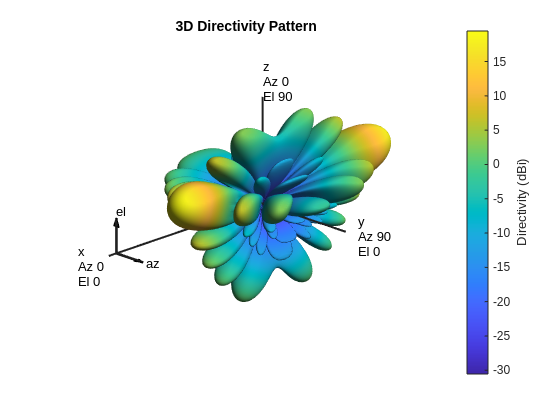

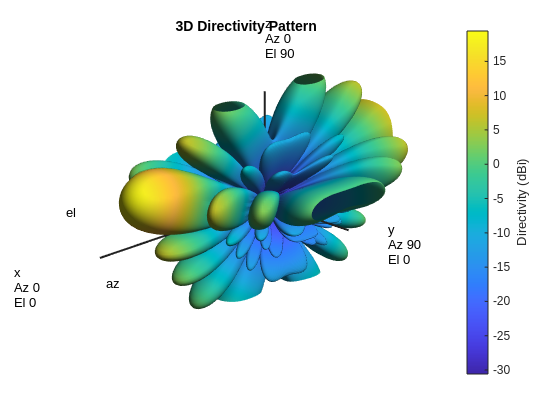

phi_scan = 10:1:10;   % Range of azimuth angles to scan
theta_scan = 15:1:15; % Range of elevation angles to scan
sz_sig = [length(phi_scan) length(theta_scan) height(signal)]; % azimuth x elevation x snapshot
sz_pwr = [length(phi_scan) length(theta_scan)];
sig_mvdr = zeros(sz_sig);
sig_cbf = zeros(sz_sig);
sig_cbf_manual = zeros(sz_sig);
P_mvdr2 = zeros(sz_pwr);  % Initialize power vector

m = 0:M-1; % [0, 1, 2, ..., M-1]
n = transpose(0:N-1); % [0, 1, 2, ..., N-1]

for i = 1:length(phi_scan)
    for j = 1:length(theta_scan)
        % Current scan angle
        phi = phi_scan(i);
        theta = theta_scan(j);
        steervec = phased.SteeringVector('SensorArray',ura, 'PropagationSpeed',c);
        a = steervec(fc, [phi; theta])

        % u = dx*sind(theta)*cosd(phi);
        % v = dy*sind(theta)*sind(phi);
        % a_manual = exp(-1j*(2*pi/lambda)*(m*u + n*v));
        % a_manual = a_manual(:)
        
        % Direction Cosines
        theta_phys = theta;
        phi_phys = phi;
        u = sind(theta_phys) * cosd(phi_phys);
        v = sind(theta_phys) * sind(phi_phys);
        % Manual steering vector calculation
        k = 2 * pi / lambda; % Wave number
        phase_shifts = 1j * k * (pos_col * u + pos_row * v);
        a_manual = exp(phase_shifts).' % Column vector

        % pattern(ura, fc);
        figure;
        pattern(ura, fc, 'Weights', a);
        figure;
        pattern(ura, fc, 'Weights', a_manual);

        %w = inv(R) * (a / (a' * inv(R) * a));
        %sig_mvdr(i,1:Nsamp) = signal * w;
        sig_cbf(i,j,1:Nsamp) = signal * a;
        sig_cbf_manual(i,j,1:Nsamp) = signal * a_manual;
        %P_mvdr2(i) = 1 / (a' * inv(R) * a);  % MVDR spectral power
    end
end

% figure;
% plot(a, '*');
% hold on;
% plot(a_manual, '*');
% hold on;
% plot(exp(1j*(0:0.01:2*pi)));
% P_mvdr = mean(abs(sig_mvdr).^2, 2);
P_cbf = mean(abs(sig_cbf).^2, 3);
P_cbf_manual = mean(abs(sig_cbf_manual).^2, 3);

Plot signals

% figure;
% plotsamps = min(Nsamp, 20);
% [x, y] = meshgrid(1:plotsamps, theta_scan);
% mesh(x, y, real(sig_cbf(1:length(theta_scan), 1:plotsamps)));
% ylabel('Steering Angle (degrees)');
% xlabel('Sample (first 20)');
% title('Conventional beamformer signal in time domain (MATLAB)');
% mesh(x, y, real(sig_cbf_manual(1:length(theta_scan), 1:plotsamps)));
% ylabel('Steering Angle (degrees)');
% xlabel('Sample (first 20)');
% title('Conventional beamformer signal in time domain (manual)');
% mesh(x, y, real(sig_mvdr(1:length(theta_scan), 1:plotsamps)));
% ylabel('Steering Angle (degrees)');
% xlabel('Sample (first 20)');
% title('MVDR beamformer result in time domain');
% grid on;

Normalize spectrum

% P_mvdr = P_mvdr/max(P_mvdr);
% P_mvdr2 = P_mvdr2/max(P_mvdr2);
% P_cbf = P_cbf/max(P_cbf);

Plot results

figure;
% plot(theta_scan, 10*log10(P_cbf), '-', 'LineWidth', 2);  % Convert power to dB
% hold on;
% plot(theta_scan, 10*log10(P_mvdr), '-', 'LineWidth', 2);  % Convert power to dB
% hold on;
% plot(theta_scan, 10*log10(P_mvdr2), '--', 'LineWidth', 2);  % Convert power to dB
% hold off;
[x, y] = meshgrid(theta_scan, phi_scan); % theta and phi swapped on purporse
pcolor(x, y, P_cbf);

Error using pcolor (line 18)
Color data input must be a matrix.

ylabel('Azimuth (degrees)');
xlabel('Elevation (degrees)')
zlabel('Normalized Spatial Spectrum (dB)');
title('Spatial Spectrum Estimation (MATLAB CBF)');
pcolor(x, y, P_cbf_manual);
ylabel('Azimuth (degrees)');
xlabel('Elevation (degrees)')
zlabel('Normalized Spatial Spectrum (dB)');
title('Spatial Spectrum Estimation (manual CBF)');
% legend('Conventional Beamforming', 'MVDR, Conventional method', 'MVDR, Calculating power directly');  % Add a legend
grid on;